# Laboratory nr 3 - aerial robotics

## Task nr 3 - trajectories

## square trajectory

clear

function [x_d, y_d, z_d, yaw_d] = square_trajectory(x_c, y_c, z_c, yaw_c, offsets)

    persistent idx
    if isempty(idx)
        idx = 1;
        
        
    end
    
    % x, y, z, yaw, notation
    traject = [1, 3, 1, 0;
        1, 3, 1, pi/2;
        1, 5, 1, pi/2;
        1, 5, 1, pi;
        -1, 5, 1, pi;
        -1, 5, 1, -pi/2;
        -1, 3, 1, -pi/2;
        -1, 3, 1, 0];

    pt = traject(idx, :);
    x_d = pt(1);
    y_d = pt(2);
    z_d = pt(3);
    yaw_d = pt(4);

    if (abs(x_d-x_c) < offsets(1)) && (abs(y_d-y_c) < offsets(2)) && (abs(z_d - z_c) < offsets(3)) && (abs(wrapToPi(yaw_d - yaw_c)) < offsets(4))
        idx = idx + 1;
        if idx > size(traject, 1)
            idx = 1;
        end
    end


end

## circular trajectory with drone heading towards center of the circle

function [x_d, y_d, z_d, yaw_d] = circular_trajectory(x_c, y_c, z_c, yaw_c, offsets)

    persistent idx
    if isempty(idx)
        idx = 1;
    
    
    end
    N = 20;
    radius = 1;
    angles = linspace(0, 2*pi, N)';
    x = cos(angles) * radius;
    y = sin(angles) * radius;
    
    yaw = wrapToPi(angles - pi);
    z = ones(1, N)';
    
    % x, y, z, yaw, notation
    traject = [x, y, z, yaw];
    
    pt = traject(idx, :);
    x_d = pt(1);
    y_d = pt(2);
    z_d = pt(3);
    yaw_d = pt(4);
    
    if (abs(x_d-x_c) < offsets(1)) && (abs(y_d-y_c) < offsets(2)) && (abs(z_d - z_c) < offsets(3)) && (abs(wrapToPi(yaw_d - yaw_c)) < offsets(4))
        idx = idx + 1;
        if idx > size(traject, 1)
            idx = 1;
        end
    end


end

## circle rotated

function [x_d, y_d, z_d, yaw_d] = circular_rotated(x_c, y_c, z_c, yaw_c, offsets)

persistent idx
if isempty(idx)
    idx = 1;


end
N = 20;
radius = 1;
angles = linspace(0, 2*pi, N)';
x = cos(angles) * radius;
y = sin(angles) * radius;

yaw = wrapToPi(angles - pi);
z = ones(1, N)';

% x, y, z, yaw, notation
inclination = rotz(45, 'deg'); % creating rotation matrix here
traject = [x, y, z];
traject = traject*inclination;
traject = [traject, yaw];

pt = traject(idx, :);
x_d = pt(1);
y_d = pt(2);
z_d = pt(3);
yaw_d = pt(4);

if (abs(x_d-x_c) < offsets(1)) && (abs(y_d-y_c) < offsets(2)) && (abs(z_d - z_c) < offsets(3)) && (abs(wrapToPi(yaw_d - yaw_c)) < offsets(4))
    idx = idx + 1;
    if idx > size(traject, 1)
        idx = 1;
    end
end


end

## some tests

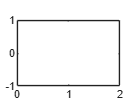

radius = 1;
angles = linspace(0, 2*pi, 20)';
x = cos(angles) * radius;
y = sin(angles) * radius;
z = ones(20, 1);
yaw = wrapToPi(angles - pi);

plot(x(1), y(1))

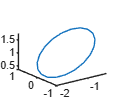


inclination = roty(45, 'deg'); % creating rotation matrix here
traject = [x, y, z];
traject = traject*inclination;
plot3(traject(:,1), traject(:,2), traject(:,3))